# Prey-Predator population

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves for the predator and prey populations for 3 weeks, with 10 prey and 2 predators initially.

tRange = [0 30];
Y0 = [10;2];
[tSol,YSol] = ode45(@odefun,tRange,Y0);

## Task 1

Extract the *prey* population.

x = YSol(:,1);

## Task 2

Extract the *predator* population.

y = YSol(:,2);

## Task 3

Plot the prey population.

plot(tSol,x)

## Task 4

Add a plot of the predator population.

hold on
plot(tSol,y)
hold off

## Task 5

Add a legend.

legend('prey','predator')

## Task 6

Find the maximum *predator* population.

ymax = max(y)

Do not edit. This code defines the ODE function for the system of ODEs

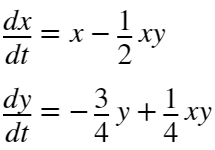

function dYdt = odefun(t,Y)
    x = Y(1); % prey
    y = Y(2); % predator
    dxdt = x - 1/2*x*y;
    dydt = -3/4*y + 1/4*x*y;
    dYdt = [dxdt;dydt];
end